对于一个二阶微分方程：


$$\ddot{x}+2\zeta\omega_n\dot{x}+\omega_n^2x=\omega_n^2u$$


作拉氏变换：


$$s^2-sX(0)-{X(0)}' + 2\zeta\omega_n[sX-X(0)]+\omega_n^2X=\omega_n^2U$$


假设初始条件为零，


$$s^2 + 2\zeta\omega_nsX+\omega_n^2X=\omega_n^2U$$


传递函数为：


$$G(s)=\frac{X(s)}{U(s)}=\frac{\omega_n^2}{s^2+2\zeta\omega_n+\omega_n^2}$$


取状态向量$x_1=x, x_2=\dot{x}
$，状态方程为：


$$\dot{x_1}=\dot{x}=x_2
\\ \dot{x_2}=\ddot{x}=-\omega_n^2x_1-2\zeta\omega_nx_2+\omega_n^2u$$


写为紧凑形式：


$$\dot{x}=Ax+Bu$$


clc
clear
close all

%%%%%%%% 定义被控系统 %%%%%%%%%
global Wn zeta
Wn = 1;         % 固有频率 1rad/s
zeta = 0.5;     % 欠阻尼
Num = [Wn^2];
Den = [1, 2*zeta*Wn, Wn^2]; 

sys = tf(Num, Den)

sys =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



pole(sys)       % 系统有两个具有负实部的极点，系统稳定

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


## 使用PID控制器

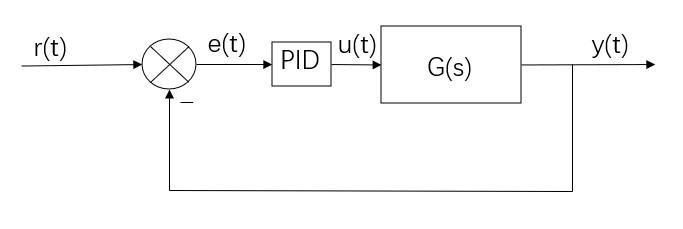

闭环控制

PID的作用在于根据误差e(t)来计算控制信号u(t)，而不是直接将方波信号输入控制系统G(s)，因此重点在于u(t)的计算。

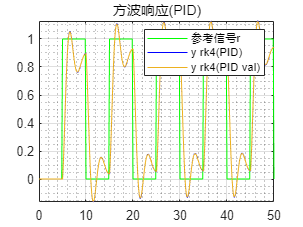

% 初始化PID
Kp = 3;
Ki = 0.5;
Kd = 0.5;
global sum_e e_last
sum_e = 0;     
e_last = 0;

tau = 10;
Tmax = 50;
X0 = [0;0];
h = 0.01;
T = 0:h:Tmax;
[r,t] = gensig('square',tau,Tmax);  % 参考信号

%%%%%%%% 使用龙格库塔法求解系统响应 %%%%%%%%
N=length(T);
X=zeros(length(X0),N);
X(:,1)=X0;
for i =2:N        
    X_k = X(:,i-1);
    t_k = T(i-1);
    
    if mod(t_k, tau) <=5
        ref = 0;
    else
        ref = 1;
    end
    
    u = PID(ref, X_k(1), h, Kp, Ki, Kd);
    
    K1=fnc(t_k,X_k, u);
    K2=fnc(t_k+h/2,X_k+h/2*K1, u);
    K3=fnc(t_k+h/2,X_k+h/2*K2, u);
    K4=fnc(t_k+h,X_k+h*K3, u);
    
    X(:,i)=X_k + h/6*(K1+2*K2+2*K3+K4);
end

% 使用simulink对系统做仿真，利用仿真结果对算法做验证
val = sim("test.slx");

figure()
plot(t, r, 'g', T, X(1,:),'b', val.y.time, val.y.data) % X(1,:)为系统的输出
title("方波响应(PID)")
legend("参考信号r","y rk4(PID)", "y rk4(PID val)")
grid on
grid minor

从右图可以看出，y rk4(PID)和y rk4(PID val)的图像几乎重合，说明使用**龙格库塔法**求解带**PID控制器**系统输出的算法是正确的。

接下来使用**粒子群算法**对PID的参数进行调节。

function dx = fnc(t, x, u)
    global Wn zeta
    dx = zeros(length(x), 1);
    dx(1) = x(2);
    dx(2) = -Wn^2*x(1) - 2*zeta*Wn*x(2) + Wn^2*u;
end
